# Optimal Beamforming with Null Steering

% Number of antenna elements (same for tx and rx)
% Assume each antenna is .5 wavelengths apart
n = 16; 

% Target Bearings
thetaT = deg2NormUnits([-10 30]); % normalized angle units
% Clutter (Interference) Bearings
thetaC = deg2NormUnits([20 60]); % normalized angle units

% Create transfer matrices for target and clutter
% Equal weighting for all targets and clutter
HT = create_mat(n,thetaT);
HC = create_mat(n,thetaC);

## Linear Constrained Optimization

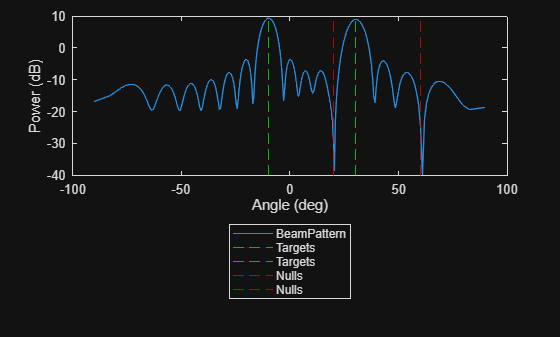

% Projection Operator
% Projects all possible solutions onto the nullspace of HC
% The projection operation onto the subspace spanned by HC is HC'*HC
% inv(HC*HC') normalizes the projection operation.
% I-P_(HC) projects onto the compliment or nullspace of HC,
% which is exactly what we want since these are the nulls we want to set
% Then, we can perform unconstrained optimization
% This treats all nulls equally in that it aims to output nothing at those
% angles
% NOTE: A lot of the literature will have the transposed/non-transposed
% matrices switched. This is because the rows of HC would typically be the
% columns.
P = eye(n) - HC'*inv(HC*HC')*HC;

% Now we can perfomr the unconstrained optimization problem
[vecs,vals] = eig(P'*(HT'*HT)*P);
[maxval,idx] = max(diag(vals));
bfWeights = vecs(:,idx);
nfft = 256;
beamPattern = mag2db(abs(fftshift(fft(bfWeights,nfft))));
plotBeamPattern(beamPattern,thetaT,thetaC)

## Generalized Rayleigh Quotient

The roblem can be formulated as a general eignevalue problem ${H^{\prime } }_T H_T \mathit{\mathbf{s}}=\lambda {H^{\prime } }_C H_C \mathit{\mathbf{s}}\;$. MATLAB easily solves this using the `eig()` function. Because the ${H^{\prime } }_C H_C$ matrix is rank deficienct (unless there are 16 nulls), we apply diagnal loading to this product.

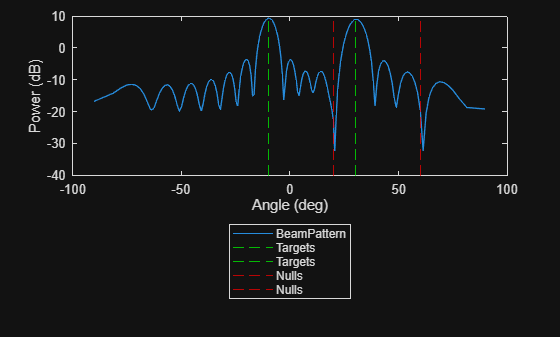

[vecs,vals] = eig((HT'*HT),HC'*HC+eye(n));
[~,idx] = max(diag(vals));
bfWeights = vecs(:,idx);
bfWeights = bfWeights / norm(bfWeights);
nfft = 180;
beamPattern = mag2db(abs(fftshift(fft(bfWeights,nfft))));
plotBeamPattern(beamPattern,thetaT,thetaC)

### Weighting Certain Nulls Differently

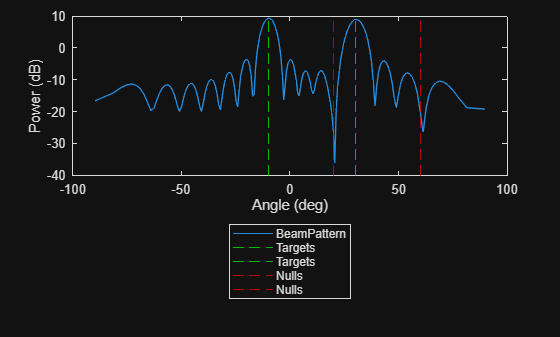

% Design the nulls such that they are weighted differently
alphaC = [10 .3];
HC = create_mat(n,thetaC,alphaC);
[vecs,vals] = eig((HT'*HT),HC'*HC+1*eye(n));
[~,idx] = max(diag(vals));
bfWeights = vecs(:,idx);
bfWeights = bfWeights / norm(bfWeights);
nfft = 180;
beamPattern = mag2db(abs(fftshift(fft(bfWeights,nfft))));
plotBeamPattern(beamPattern,thetaT,thetaC)

## Helper Functions

function H = create_mat(n,theta,alpha)
    if nargin < 3
        alpha = ones(size(theta));
    end
    numReflectors = numel(theta);
    H = zeros(numReflectors,n);
    for ii = 1:numReflectors
        for jj = 1:n
            for aa = 1:numReflectors
                H(ii,jj) = H(ii,jj) + alpha(aa)*exp(1j*2*pi*(ii-jj)*theta(aa));
            end
        end
    end
end

function out = deg2NormUnits(deg)
    out = deg2rad(deg);     
    out = .5*sin(out);
end

function out = normUnits2Deg(units)
    out = rad2deg(asin(2*units));
end

function plotBeamPattern(beamPattern,thetaT,thetaC)
    x = normUnits2Deg(linspace(-.5,.5,numel(beamPattern)));
    figure; plot(x,beamPattern,'DisplayName','BeamPattern')
    hold on;
    xline(normUnits2Deg(thetaT),'--','Color','green','DisplayName','Targets')
    xline(normUnits2Deg(thetaC),'--','Color','red','DisplayName','Nulls')
    xlabel('Angle (deg)')
    ylabel('Power (dB)')
    legend('Location','southoutside')
end